 姓名：莊璧如 學號：111321534

ex1

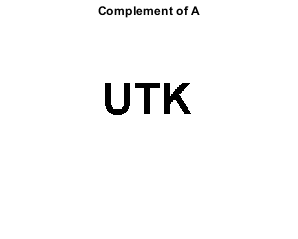

A=imread('utk.tif');
B=imread('gt.tif');
imshow(not(A));
title('Complement of A');

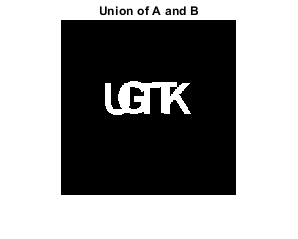

imshow(or(A,B));
title('Union of A and B');

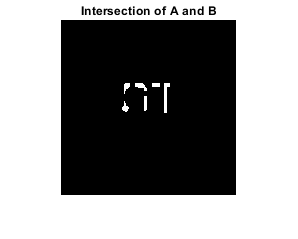

imshow(and(A,B));
title('Intersection of A and B');

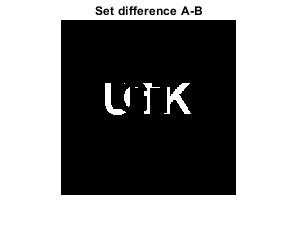

imshow(A&(~B));
title('Set difference A-B');

EX2

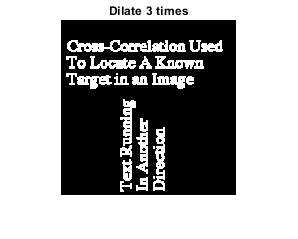

t=imread('text.tif');
sq=ones(3,3);
td=imdilate(t,sq);
sq1=ones(2,2);
td1=imdilate(t,sq1);
imshow(td)
title('Dilate 3 times');

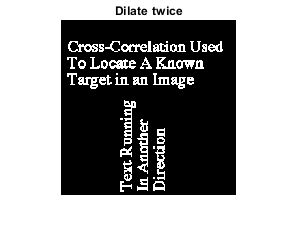

imshow(td1)
title('Dilate twice')

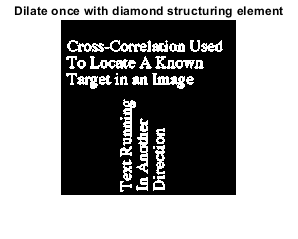

sq2=[0 1 0;1 1 1;0 1 0];
td2=imdilate(t,sq2);
imshow(td2);
title('Dilate once with diamond structuring element');

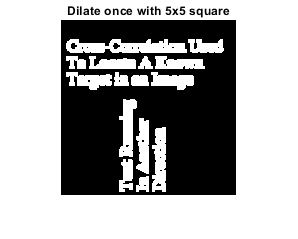

sq3=ones(5,5);
td3=imdilate(t,sq3);
imshow(td3);
title('Dilate once with 5x5 square');

ex4

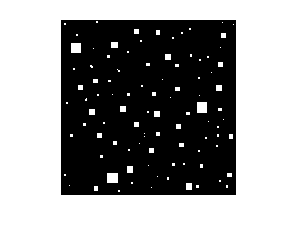

s=imread('small-squares.tif');
imshow(s)

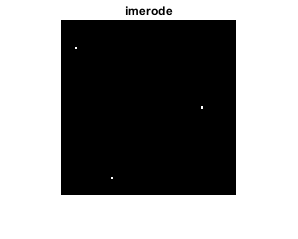

sq4=ones(13,13);
td4=imerode(s,sq4);
imshow(td4)
title('imerode')

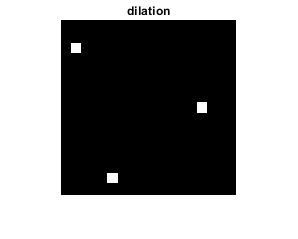

sq5=ones(13,13);
td5=imdilate(td4,sq5);
imshow(td5)
title('dilation')

ex5

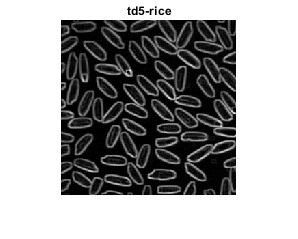

rice=imread('rice.tif');
r=rice > 110;
sq=ones(5,5);
td5=imdilate(rice,sq);
imshow(td5-rice,[])
title('td5-rice')

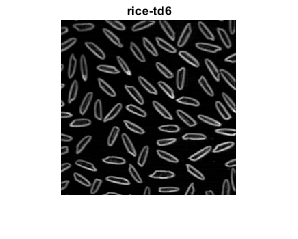

r=rice > 110;
sq=ones(5,5);
td6=imerode(rice,sq);
imshow(rice-td6,[])
title('rice-td6')

ex6

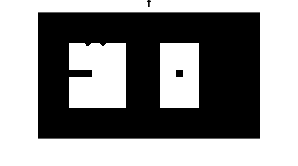

I=imread('shapes.tif');
b1=ones(20, 20);
f=imopen(I, b1);
g=imclose(I, b1);
imshow(f)
title('f')

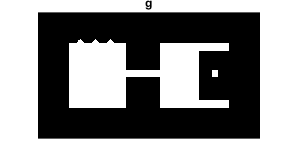

imshow(g)
title('g')

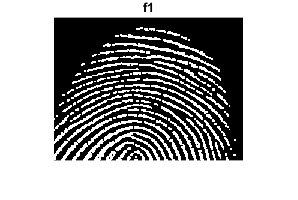

fin=imread("noisy-fingerprint.tif");
b=ones(3,3);
f1=imopen(fin, b);
g1=imclose(fin, b);
imshow(and(f1,g1))
title('f1')

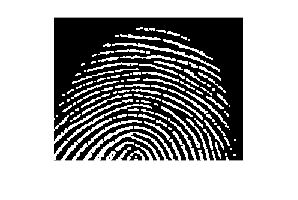

imshow(and(g1,f1))

ex7

A=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
0 0 1 0 0 0 1 1 1 1 0 0 0 0 0 0;
0 1 1 1 0 0 0 0 0 0 0 0 1 1 0 0;
0 0 1 0 0 0 1 0 0 0 0 0 1 1 1 0;
0 0 0 0 0 1 1 1 0 0 0 0 0 1 0 0;
0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0;
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     1     1     1     1     0     0     0     0     0     0
     0     1     1     1     0     0     0     0     0     0     0     0     1     1     0     0
     0     0     1     0     0     0     1     0     0     0     0     0     1     1     1     0
     0     0     0     0     0     1     1     1     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


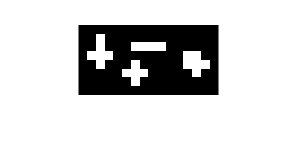

imshow(A,'InitialMagnification',1000)

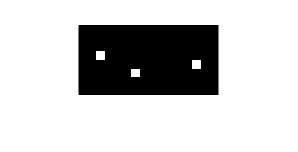

sq2=[0 1 0;1 1 1;0 1 0];
a1=imerode(A,sq2);
imshow(a1,'InitialMagnification',1000)

q=[1 1 1 1 1;1 1 0 1 1;1 0 0 0 1;1 1 0 1 1;1 1 1 1 1];
a0=~A

a0 = 8×16 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   0   1   1   1   0   0   0   0   1   1   1   1   1   1
   1   0   0   0   1   1   1   1   1   1   1   1   0   0   1   1
   1   1   0   1   1   1   0   1   1   1   1   1   0   0   0   1
   1   1   1   1   1   0   0   0   1   1   1   1   1   0   1   1
   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


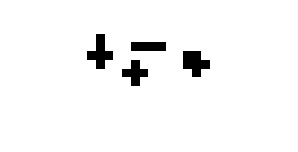

imshow(a0,'InitialMagnification',1000)

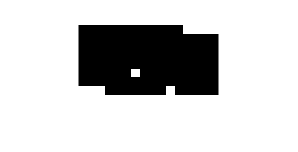

a2=imerode(a0,q);
imshow(a2,'InitialMagnification',1000)

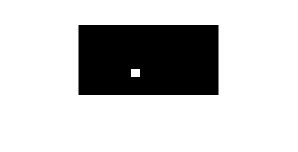

imshow(and(a1,a2),'InitialMagnification',1000)

ex8

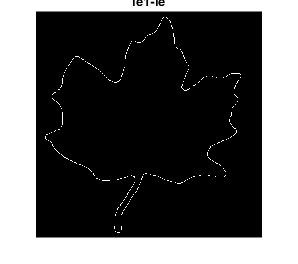

le=imread("Fig1108(a)(mapleleaf).tif");
sq=ones(3,3);
le1=imdilate(le,sq);
imshow(le1-le,[])
title('le1-le')

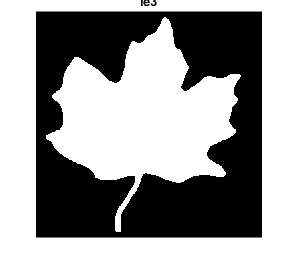

le2=imerode(le1,sq);
le3=regfill(le1-le2,[254,254],sq);
imshow(le3)
title('le3')

function out=regfill(im, pos, kernel)
% im: input image
% pos: initial (x,y)
% kernel: filling kernel
current=zeros(size(im));
last=zeros(size(im));
last(pos(1), pos(2))=1;
current=imdilate(last, kernel) & ~im;
while any(current(:) ~= last(:)),
last=current;
current=imdilate(last, kernel) & ~im;
end;
out=current;
end